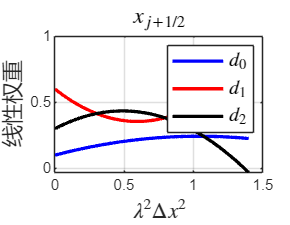

clc; clear; close all;

l2h2 = 0:0.01:1.4;

%% x_{j+1/2} (case 3)
d0_half = -(1111*l2h2.^2)/8400 + (11*l2h2)/40 + 1/10;
d1_half = (243*l2h2.^2)/350 - (33*l2h2)/40 + 3/5;
d2_half = -(4721*l2h2.^2)/8400 + (11*l2h2)/20 + 3/10;

%% x_{j+sqrt(5)/10} (case 2)
d0_inner = 91/440 + 9*sqrt(5)/440 ...
         + (2829/6050 + 5383*sqrt(5)/181500)*l2h2 ...
         + (-12064089/37268000 - 74574457*sqrt(5)/1677060000)*l2h2.^2;

d1_inner = 129/220 ...
         - (2829/3025)*l2h2 ...
         + (12064089/18634000)*l2h2.^2;

d2_inner = 91/440 - 9*sqrt(5)/440 ...
         + (2829/6050 - 5383*sqrt(5)/181500)*l2h2 ...
         + (-12064089/37268000 + 74574457*sqrt(5)/1677060000)*l2h2.^2;

%% ===== Figure 1 =====
fig1 = figure('Units','centimeters','Position',[0 0 9 7]);
hold on
plot(l2h2, d0_half, 'b',  'LineWidth', 2, 'DisplayName', '$d_0$')
plot(l2h2, d1_half, 'r', 'LineWidth', 2, 'DisplayName', '$d_1$')
plot(l2h2, d2_half, 'k',  'LineWidth', 2, 'DisplayName', '$d_2$')
xlabel('$\lambda^2 \Delta x^2$', 'Interpreter', 'latex', 'FontSize', 13)
ylabel('线性权重',          'FontSize', 13)
title('$x_{j+1/2}$',            'Interpreter', 'latex', 'FontSize', 14)
legend('Interpreter', 'latex', 'FontSize', 12);
box on; grid on;

print(fig1, 'linear_weights_half', '-depsc', '-r300')

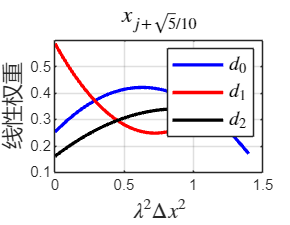


%% ===== Figure 2 =====
fig2 = figure('Units','centimeters','Position',[10 0 9 7]);
hold on
plot(l2h2, d0_inner, 'b',  'LineWidth', 2, 'DisplayName', '$d_0$')
plot(l2h2, d1_inner, 'r', 'LineWidth', 2, 'DisplayName', '$d_1$')
plot(l2h2, d2_inner, 'k',  'LineWidth', 2, 'DisplayName', '$d_2$')
xlabel('$\lambda^2 \Delta x^2$', 'Interpreter', 'latex', 'FontSize', 13)
ylabel('线性权重',          'FontSize', 13)
title('$x_{j+\sqrt{5}/10}$',    'Interpreter', 'latex', 'FontSize', 14)
legend('Interpreter', 'latex', 'FontSize', 12);
box on; grid on;

print(fig2, 'linear_weights_inner', '-depsc', '-r300')


disp('两个图已分别保存为 eps 文件')

两个图已分别保存为 eps 文件
